# FNN CNN LSTM - Get Data Plot

## Set index of each items of data

i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;
pattern_tempdx = i; i=i+1;
pattern_CC_ampsIdx = i; i=i+1;
charVIT_Index = i; 


load cap_gen_05_org
load cap_gen_06_org
load cap_gen_07_org
load cap_gen_05
load cap_gen_06
load cap_gen_07

load cap_05             
load cap_06             
load cap_07             
load cap_0506           
load cap_0605           
load cap_05plus06       
load cap_05plus07       
load cap_06plus07       
load cap_05plus06plus07 

load pattern_temp_05_const        
load pattern_temp_06_const        
load pattern_temp_07_const        
load pattern_CC_amps_05_const     
load pattern_CC_amps_06_const     
load pattern_CC_amps_07_const     
load pattern_dVolt_05_const       
load pattern_dVolt_06_const       
load pattern_dVolt_07_const  

load regression_vector_05 regression_vector_06 regression_vector_07 regression_vector_0506 regression_vector_0605 regression_vector_05plus06 regression_vector_05plus06plus07
load regression_table_05 regression_table_06 regression_table_07 regression_table_0506 regression_table_0605 regression_table_05plus06 regression_table_05plus06plus07

load idx_0506
load idx_0605

# 가우시안 프로세스 

# Compare Prediction Intervals of GPR Models

This example fits GPR models to a noise-free data set and a noisy data set. The example compares the predicted responses and prediction intervals of the two fitted GPR models. 

Generate two observation data sets from the function $g\left(x\right)=x\cdot \sin \left(x\right)$. 


%{
BAT = Y56;
BAT_NAME = 'Y56';
pattern_change_index =27;

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;

BAT = Y5;
BAT_NAME = 'Y5';
pattern_change_index =30;

BAT = Y6;
BAT_NAME = 'Y6';
pattern_change_index =30;

%}

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index = idx_0605;



%learning_start_index = 1;
learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = true;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

if use_just_observed
    % 변화된 구간 조금만 훈력
    x_observed = idxpre';
    y_observed1 =  BAT(idxpre);    
else
    % 모든 구간에 대해 훈련
    x_observed = idxall';
    y_observed1 =  BAT(idxall);   
end

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));


The values in `y_observed1` are noise free, and the values in `y_observed2` include some random noise. 

Fit GPR models to the observed data sets.

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
%}

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );




Compute the predicted responses and 95% prediction intervals using the fitted models. 

[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');


Resize a figure to display two plots in one figure.

fig = figure;
fig.Position(3) = fig.Position(3)*2;

Create a 1-by-2 tiled chart layout.

tiledlayout(1,2,'TileSpacing','compact')

For each tile, draw a scatter plot of observed data points and a function plot of $x\cdot \sin \left(x\right)$. Then add a plot of GP predicted responses and a patch of prediction intervals. 

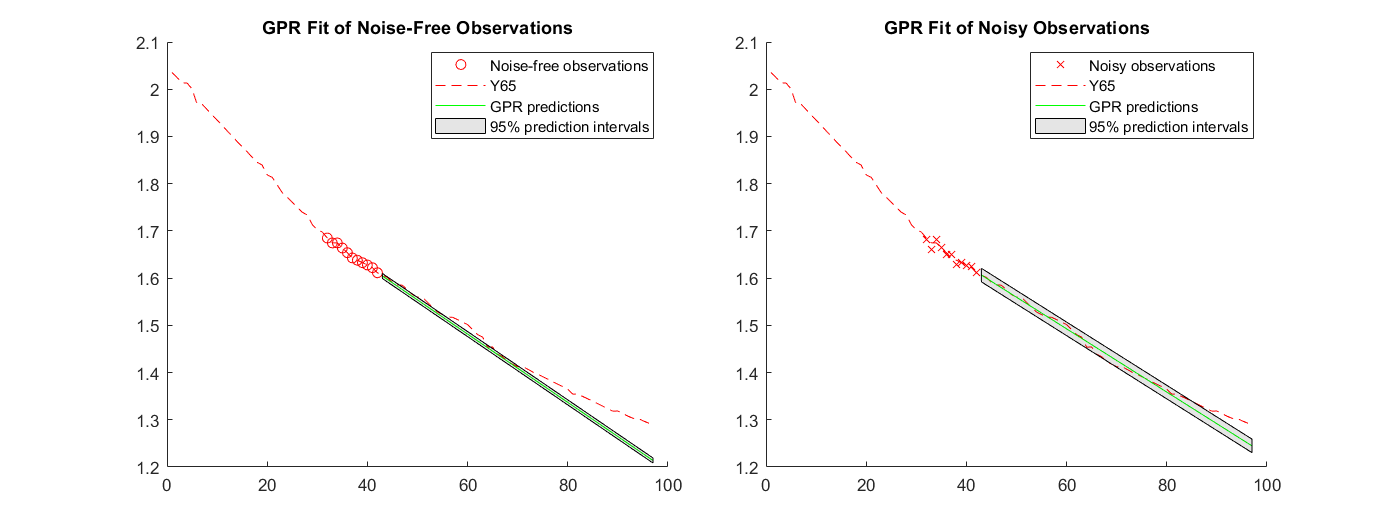

nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

GP 로는 잘 동작하지 않는다.

mean function 이 정확해야 하나 패넡 변화를 인지하더라도 mean function 이 선형적이 아니라서 결국 예측에 실패한다.

따라서 GP는 패턴별로 여러 데이타셋을 가지고 테스트 해야 의미가 있는 것 같다. 

change point들을 계속 검색하고

선형 회귀의 가중치를 이전의 측정값에 가중치를 줄이고 

최근 변화된 데이타를 가중치를 더 주면 

GP를 사요할 경우 계속 추정치가 현실에 맞게 변화될 것이다.

이는 Kalman Filter랑 비슷하다.

여기서 평가는 학습구간과 예측구간이 점차 뒤로 이동하게 된다.

이에 따른 평가를 해야 한다.

다시 보면 이는 LSTM 이라 같은 결과를 가져올 것 같다. 

관측값을 처음부터  패턴 변경 후 10번째 까지로 하자

learning_start_index = 1;

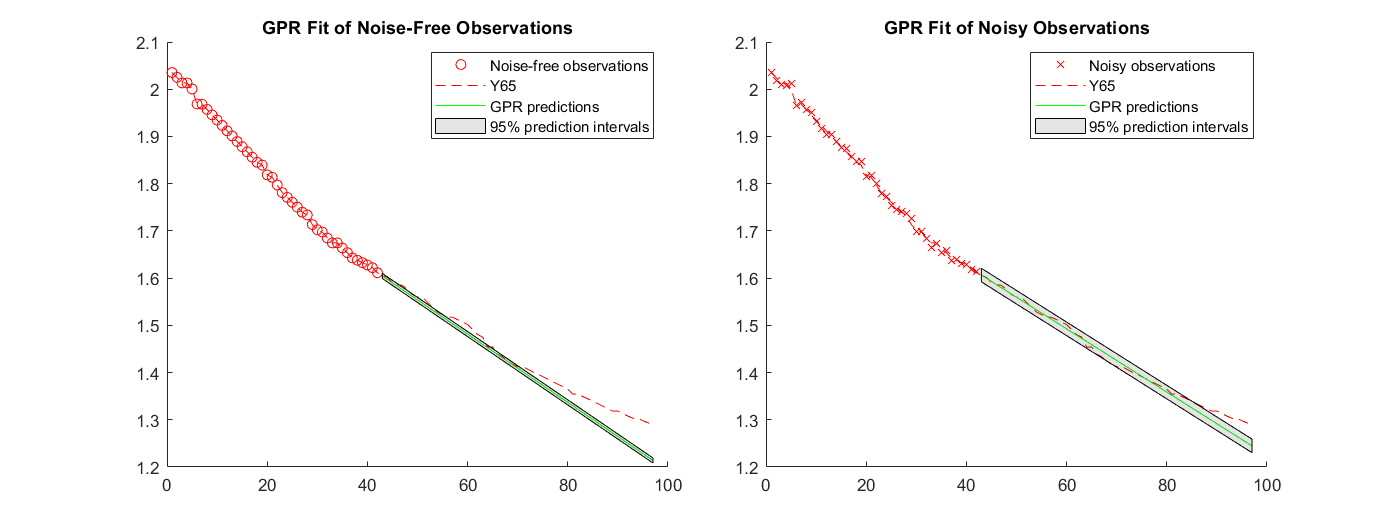

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index = idx_0605;

learning_start_index = 1;
%learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = true;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

if use_just_observed
    % 변화된 구간 조금만 훈력
    x_observed = idxpre';
    y_observed1 =  BAT(idxpre);    
else
    % 모든 구간에 대해 훈련
    x_observed = idxall';
    y_observed1 =  BAT(idxall);   
end

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
%}

%{
gprMdl1 = fitrgp(x_observed,y_observed1,"Basis","constant","KernelFunction" , "squaredexponential" , ...
    'OptimizeHyperparameters','auto',"FitMethod" , "exact" , "PredictMethod" , "exact" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"Basis","constant","KernelFunction" , "squaredexponential" , ...
    'OptimizeHyperparameters','auto',"FitMethod" , "exact" , "PredictMethod" , "exact" , "Standardize" , 1 );
%}

[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

관측값을 전체로 하면 실제값과 예측값이 같다.

use_just_observed = false;

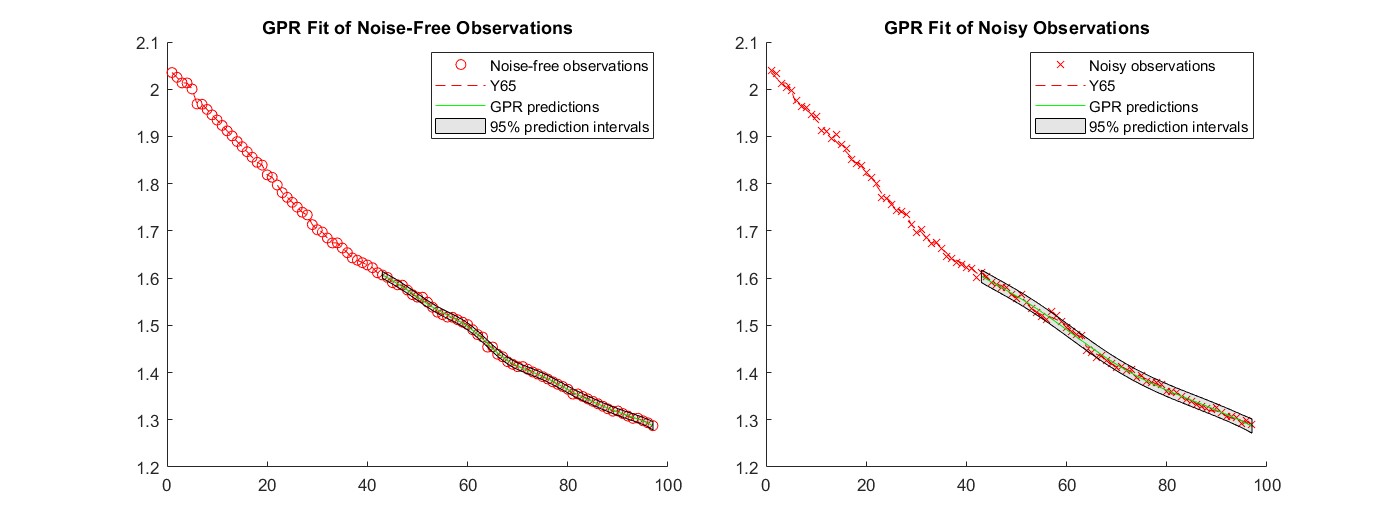

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index = idx_0605;



%learning_start_index = 1;
learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = false;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

if use_just_observed
    % 변화된 구간 조금만 훈력
    x_observed = idxpre';
    y_observed1 =  BAT(idxpre);    
else
    % 모든 구간에 대해 훈련
    x_observed = idxall';
    y_observed1 =  BAT(idxall);   
end

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
%}

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );


[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

GP는 관측값이 작은 경우에서 큰 경우로 변경되면서 예측력이 우수해진다.  => 베이지안 기반 가우시안 프로세스

작은 관측값으로 먼저 피팅하고 새 관측값을 추가해보자.

1 6 11 16 22 26 31 36 41

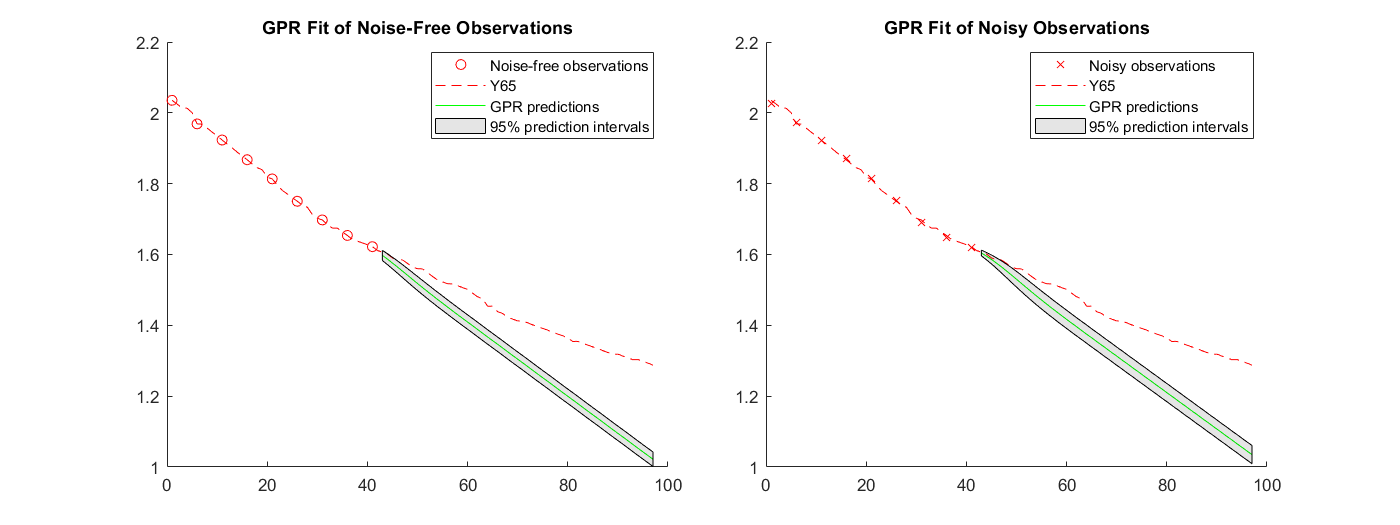

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index = idx_0605 ;
BAT_sample = BAT(1:5:end); %21
%x_sample = [1:5:length(BAT)];
x_sample = [1:5:41]; % 41 51 61

learning_start_index = 1;
%learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = false;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

    x_observed = x_sample';
    y_observed1 =  BAT(x_sample);    

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

%}
gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );


[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

GP는 관측값이 작은 경우에서 큰 경우로 변경되면서 예측력이 우수해진다.  => 베이지안 기반 가우시안 프로세스

작은 관측값으로 먼저 피팅하고 새 관측값을 추가해보자.

변경된 시점부터 다시 시작한다.

31 36 41

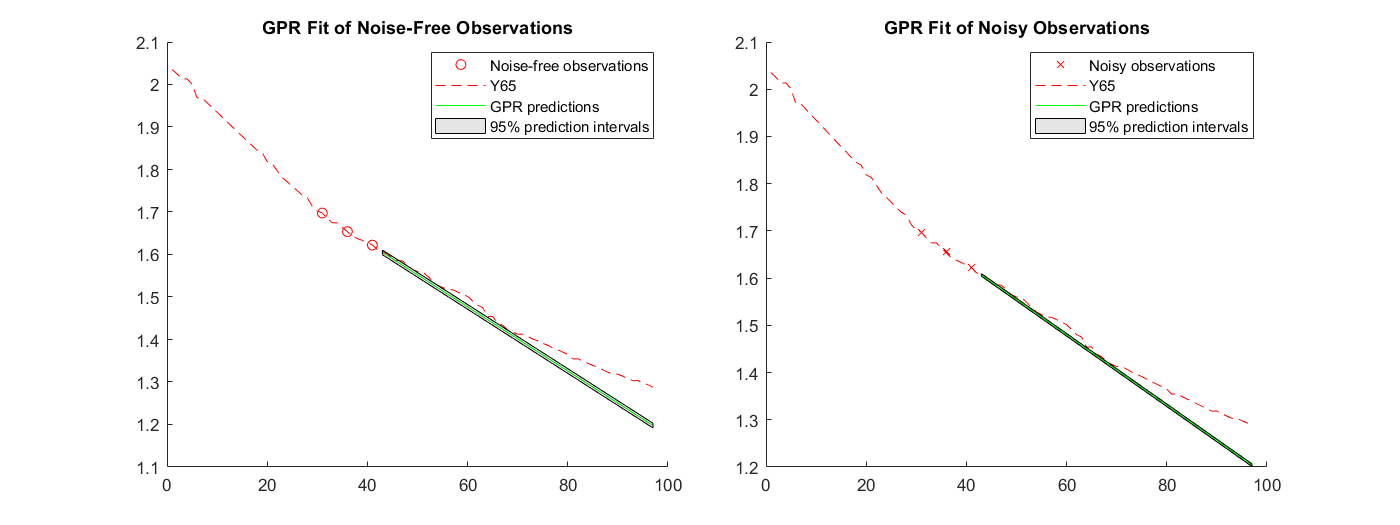

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index = idx_0605 ;
BAT_sample = BAT(1:5:end); %21
%x_sample = [1:5:length(BAT)];
x_sample = [31 36 41]; % 41 51 61

learning_start_index = 1;
%learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = false;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

    x_observed = x_sample';
    y_observed1 =  BAT(x_sample);    

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

%}
gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );


[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')